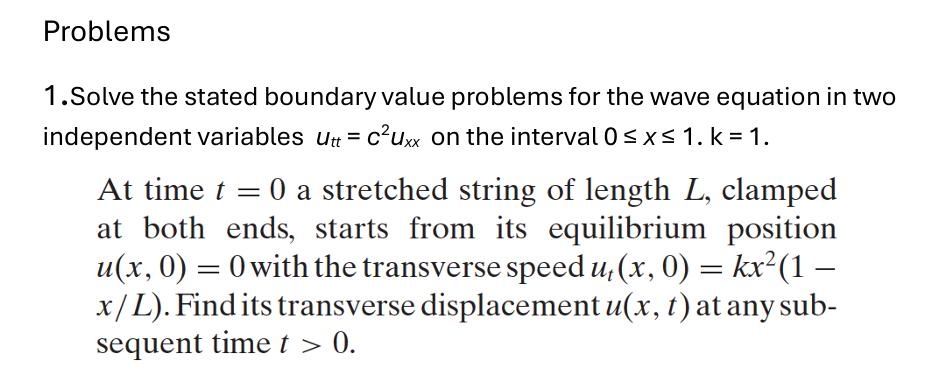

clf;
clearvars
%parameters
L = 1;           
c = 1;           
k = 1;          
N = 100;         
x = linspace(0, L, 100); % Spatial 
t = linspace(0, 2, 100); % Temporal 
[X, T] = meshgrid(x, t);
u = zeros(size(X));

**Fourier series solution**

for n = 1:N
    omega_n = n * pi * c / L;
    bn = (2 * k / (n^3 * pi^3)) * (1 - (-1)^n);
    u = u + bn * sin(n * pi * X / L) .* sin(omega_n * T);
end

**Plot graph**

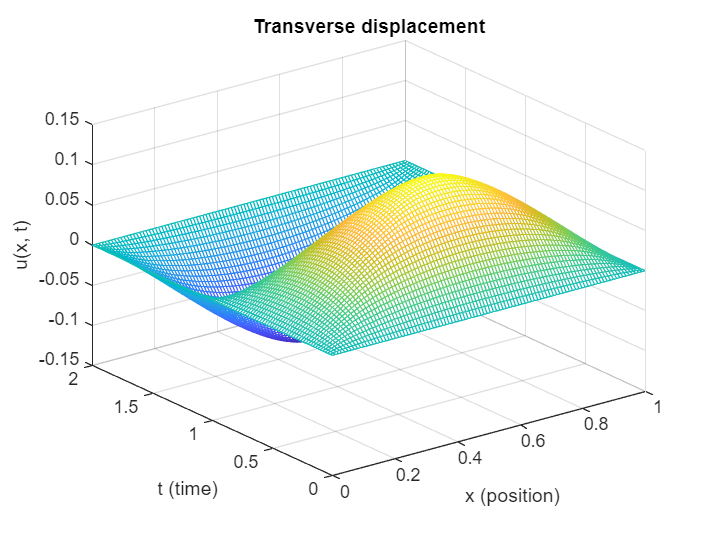

figure
mesh(X, T, u);
xlabel('x (position)');
ylabel('t (time)');
zlabel('u(x, t)');
title('Transverse displacement');